## fCWT for MATLAB example

First, create the signal that has been used as artificial dataset in the paper. This dataset consists of three wave packets joined together. 

clear

%Sampling frequency
fs = 500;

%intermediate wave packet containing a zero signal
t0 = (1/fs:1/fs:0.5)';
p0 = 0*t0;

%1st wave packet
t1 = (1/fs:1/fs:5)';
p1_final = vco(cos(2*pi*t1),[100 110],fs) + ...
            vco(cos(2*pi*t1),[20 22],fs) + ...
            vco(cos(2*pi*t1),[5 6],fs);
L1 = length(p1_final)/10;
p1_ham = hamming(L1*2);
p1_window = [ones(L1*9,1); p1_ham(L1:(L1*2-1))];
p1 = p1_final.*p1_window;

%2nd wave packet
t2 = (1/fs:1/fs:5)';
p2_base = chirp(t2,100,5,50);
p2_final = p2_base + chirp(t2,5,5,50);

L2 = length(p2_final)/10;
p2_ham = hamming(L2*2);
p2_window = [p2_ham(1:L2); ones(L2*8,1); p2_ham(L2:(L2*2-1))];
p2 = p2_final.*p2_window;

%3rd wave packet
t3 = (1/fs:1/fs:10)';
p3_final = cos(2*pi*t3*(fs/1000)) + cos(2*pi*t3*(fs/500)) + cos(2*pi*t3*(fs/250)); 

L3 = length(p3_final)/10;
p3_ham = hamming(L3*2);
p3_window = [p3_ham(1:L3); ones(L3*9,1)];
p3 = p3_final.*p3_window;

%Join all wave packets
signal = [p1; p0; p2; p0 ; p3];


ts = linspace(0,length(signal)/fs,length(signal));
xtick = round(linspace(1,length(signal),8));

%Create the second artificial dataset by applying SNR=0dB (1:1) Gaussian noise
noise = signal;

g0 = 10^(0/10);
power = sum(abs(noise).^2)/length(noise);
noise = noise+sqrt(power/(2*g0))*randn(size(noise));

Calculate optimization plans for fCWT with respect to our current hardware setup and signal length.

fCWT_create_plan(length(signal),1,'measure')

Using 'measure' to calculate plan 

using N:10500Calculating optimal scheme for forward FFT with N:2048
Calculating optimal scheme for backward FFT with N:2048
Optimization schemes for N: 2048 have been calculated. Next time you use fCWT it will automatically choose the right optimization scheme based on number of threads and signal length.
Calculating optimal scheme for forward FFT with N:4096
Calculating optimal scheme for backward FFT with N:4096
Optimization schemes for N: 4096 have been calculated. Next time you use fCWT it will automatically choose the right optimization scheme based on number of threads and signal length.
Calculating optimal scheme for forward FFT with N:8192
Calculating optimal scheme for backward FFT with N:8192
Optimization schemes for N: 8192 have been calculated. Next time you use fCWT it will automatically choose the right optimization scheme based on number of threads and signal length.
Calculating optimal scheme for forward FFT with N:16384
Calculating optimal scheme for backward FFT with 

Plot both artificial datasets and the corresponding time-frequency spectra

%Create figure 
dpi = 150;
figure('Renderer', 'painters', 'Position', [0 0 18*dpi 7*dpi])

%Initialize grid parameters such as margins and cell width/height
outwmargin = 0.075;
outhmargin = 0.05;
wmargin = 0.015;
hmargin = 0.02;
celw = (1-outwmargin*2)/7;
celh = (1-outhmargin*2)/3;

%Create shortcuts for cell widths and heights
w1 = celw-wmargin*2;
w3 = celw*3-wmargin*2;
h1 = celh-hmargin*2;

col1 = outwmargin+wmargin;
col4 = outwmargin+celw*3+wmargin;
col5 = outwmargin+celw*4+wmargin;

%Define colormap used
cm = jet();

%Frequency scale labels
freqlabelslog = [100 20 5 0];


%%=====================================================
%%================= Signal ============================
%%=====================================================
ax = axes('Position',[col1,1-outhmargin-celh*1-hmargin,w3,h1]);

plot(ts,signal,'LineWidth',1);
xlim([0 21])
axis off;

ttl = title('a) Synthetic data');
ttl.FontSize = 30;
ttl.Units = 'Normalize'; 
ttl.Position(1) = -0.02; % use negative values (ie, -0.1) to move further left
ttl.HorizontalAlignment = 'left';  

xticklabels([]);

%%=====================================================
%%================= Noise  ============================
%%=====================================================
ax = axes('Position',[col5,1-outhmargin-celh*1-hmargin,w3,h1]);

plot(ts,noise,'LineWidth',1)
xlim([0 21])
axis off;

ttl = title('b) SNR=0dB');
ttl.FontSize = 30;
ttl.Units = 'Normalize'; 
ttl.Position(1) = -0.02;
ttl.HorizontalAlignment = 'left';  


%=====================================================
%================= fCWT ==============================
%=====================================================
ax = axes('Position',[col1,1-outhmargin-celh*2-hmargin,w3,h1]);

A = single(signal.');
tic;
[B,fcwtf] = fCWT(A,1,fs,0.25,250,480,1);


fCWTtime = toc

fCWTtime = 0.0539

fcwt_tfm_sig = abs(B.');
image(fcwt_tfm_sig,"CDataMapping","scaled");
colormap(cm);

ttl = title('fCWT');
ttl.FontSize = 30;
ttl.Units = 'Normalize'; 
ttl.Position(1) = -0.15; % use negative values (ie, -0.1) to move further left
ttl.Position(2) = 0.5;
ttl.Rotation = 90;
ttl.HorizontalAlignment = 'center';

[~,ypos] = min(abs(fcwtf-freqlabelslog.').');
yticks(ypos);
yticklabels(freqlabelslog);
xticklabels([]);
ylabel("Frequency (Hz)");

ax.XAxis.FontSize = 20;
ax.YAxis.FontSize = 20;
ax.XLabel.FontSize = 24;
ax.YLabel.FontSize = 24;

rectangle('Position',[17*fs 250 2*fs 230],'LineWidth',2)
set(gca,'Clipping','Off')
line([19*fs 22.9*fs],[250 0],'Color','black','LineWidth',1)
line([19*fs 22.9*fs],[480 480],'Color','black','LineWidth',1)

%================ Zoom-in ============================
ax = axes('Position',[col4,1-outhmargin-celh*2-hmargin,w1,h1]);

image(fcwt_tfm_sig(:,(17*fs):(19*fs)),"CDataMapping","scaled");
xticklabels([]);
ylim([250 480]);

freqlabelssmall = [4 0];
[~,ypos] = min(abs(fcwtf-freqlabelssmall.').');
yticks(ypos);
yticklabels([4 0]);
ax = gca;
colormap(cm);
ax.YAxisLocation = 'right';

ax.XAxis.FontSize = 20;
ax.YAxis.FontSize = 20;

%================== Noise ============================
ax = axes('Position',[col5,1-outhmargin-celh*2-hmargin,w3,h1]);
A= single(noise.');
tic;
[B,~] = fCWT(A,1,fs,0.25,250,480,1);

fCWTtime_noise = toc

fCWTtime_noise = 0.0440

fcwt_tfm_noise = abs(B.');

image(fcwt_tfm_noise,"CDataMapping","scaled");
colormap(cm);

[~,ypos] = min(abs(fcwtf-freqlabelslog.').');
yticks(ypos);
yticklabels(freqlabelslog);
xticklabels([]);
xlabel("");
ylabel("");
ax.YAxisLocation = 'right';

ax.XAxis.FontSize = 20;
ax.YAxis.FontSize = 20;
ax.XLabel.FontSize = 24;
ax.YLabel.FontSize = 24;


%%=====================================================
%%================== CWT ==============================
%%=====================================================
ax = axes('Position',[col1,1-outhmargin-celh*3-hmargin,w3,h1]);

tic;
[wt,cwtf] = cwt(signal,'amor',fs,'FrequencyLimits',[0.25 250],'VoicesPerOctave',48);
CWTtime = toc

CWTtime = 0.5045

cwt_tfm_sig = abs(wt);
image(cwt_tfm_sig,"CDataMapping","scaled");
ax = gca;
colormap(cm);

ttl = title('CWT');
ttl.FontSize = 30;
ttl.Units = 'Normalize'; 
ttl.Position(1) = -0.15; % use negative values (ie, -0.1) to move further left
ttl.Position(2) = 0.5;
ttl.Rotation = 90;
ttl.HorizontalAlignment = 'center';

[~,ypos] = min(abs(cwtf.'-freqlabelslog.').');
yticks(ypos);
yticklabels(freqlabelslog);
xticklabels([]);
ylabel("");

ax.XAxis.FontSize = 20;
ax.YAxis.FontSize = 20;
ax.XLabel.FontSize = 24;
ax.YLabel.FontSize = 24;

rectangle('Position',[17*fs 250 2*fs 230],'LineWidth',2)
set(gca,'Clipping','Off')
line([19*fs 22.9*fs],[250 0],'Color','black','LineWidth',1)
line([19*fs 22.9*fs],[480 480],'Color','black','LineWidth',1)

%================ Zoom-in ============================
ax = axes('Position',[col4,1-outhmargin-celh*3-hmargin,w1,h1]);
image(cwt_tfm_sig(:,(17*fs):(19*fs)),"CDataMapping","scaled");
xticklabels([]);
ylim([250 480]);

freqlabelssmall = [4 0];
[~,ypos] = min(abs(cwtf.'-freqlabelssmall.').');
yticks(ypos);
yticklabels([4 0]);

ax = gca;
colormap(cm);
ax.YAxisLocation = 'right';

ax.XAxis.FontSize = 20;
ax.YAxis.FontSize = 20;

%================== Noise ============================
ax = axes('Position',[col5,1-outhmargin-celh*3-hmargin,w3,h1]);
tic;
[wt,~] = cwt(noise,'amor',fs,'FrequencyLimits',[0.25 250],'VoicesPerOctave',48);
CWTtime_noise = toc

CWTtime_noise = 0.3709

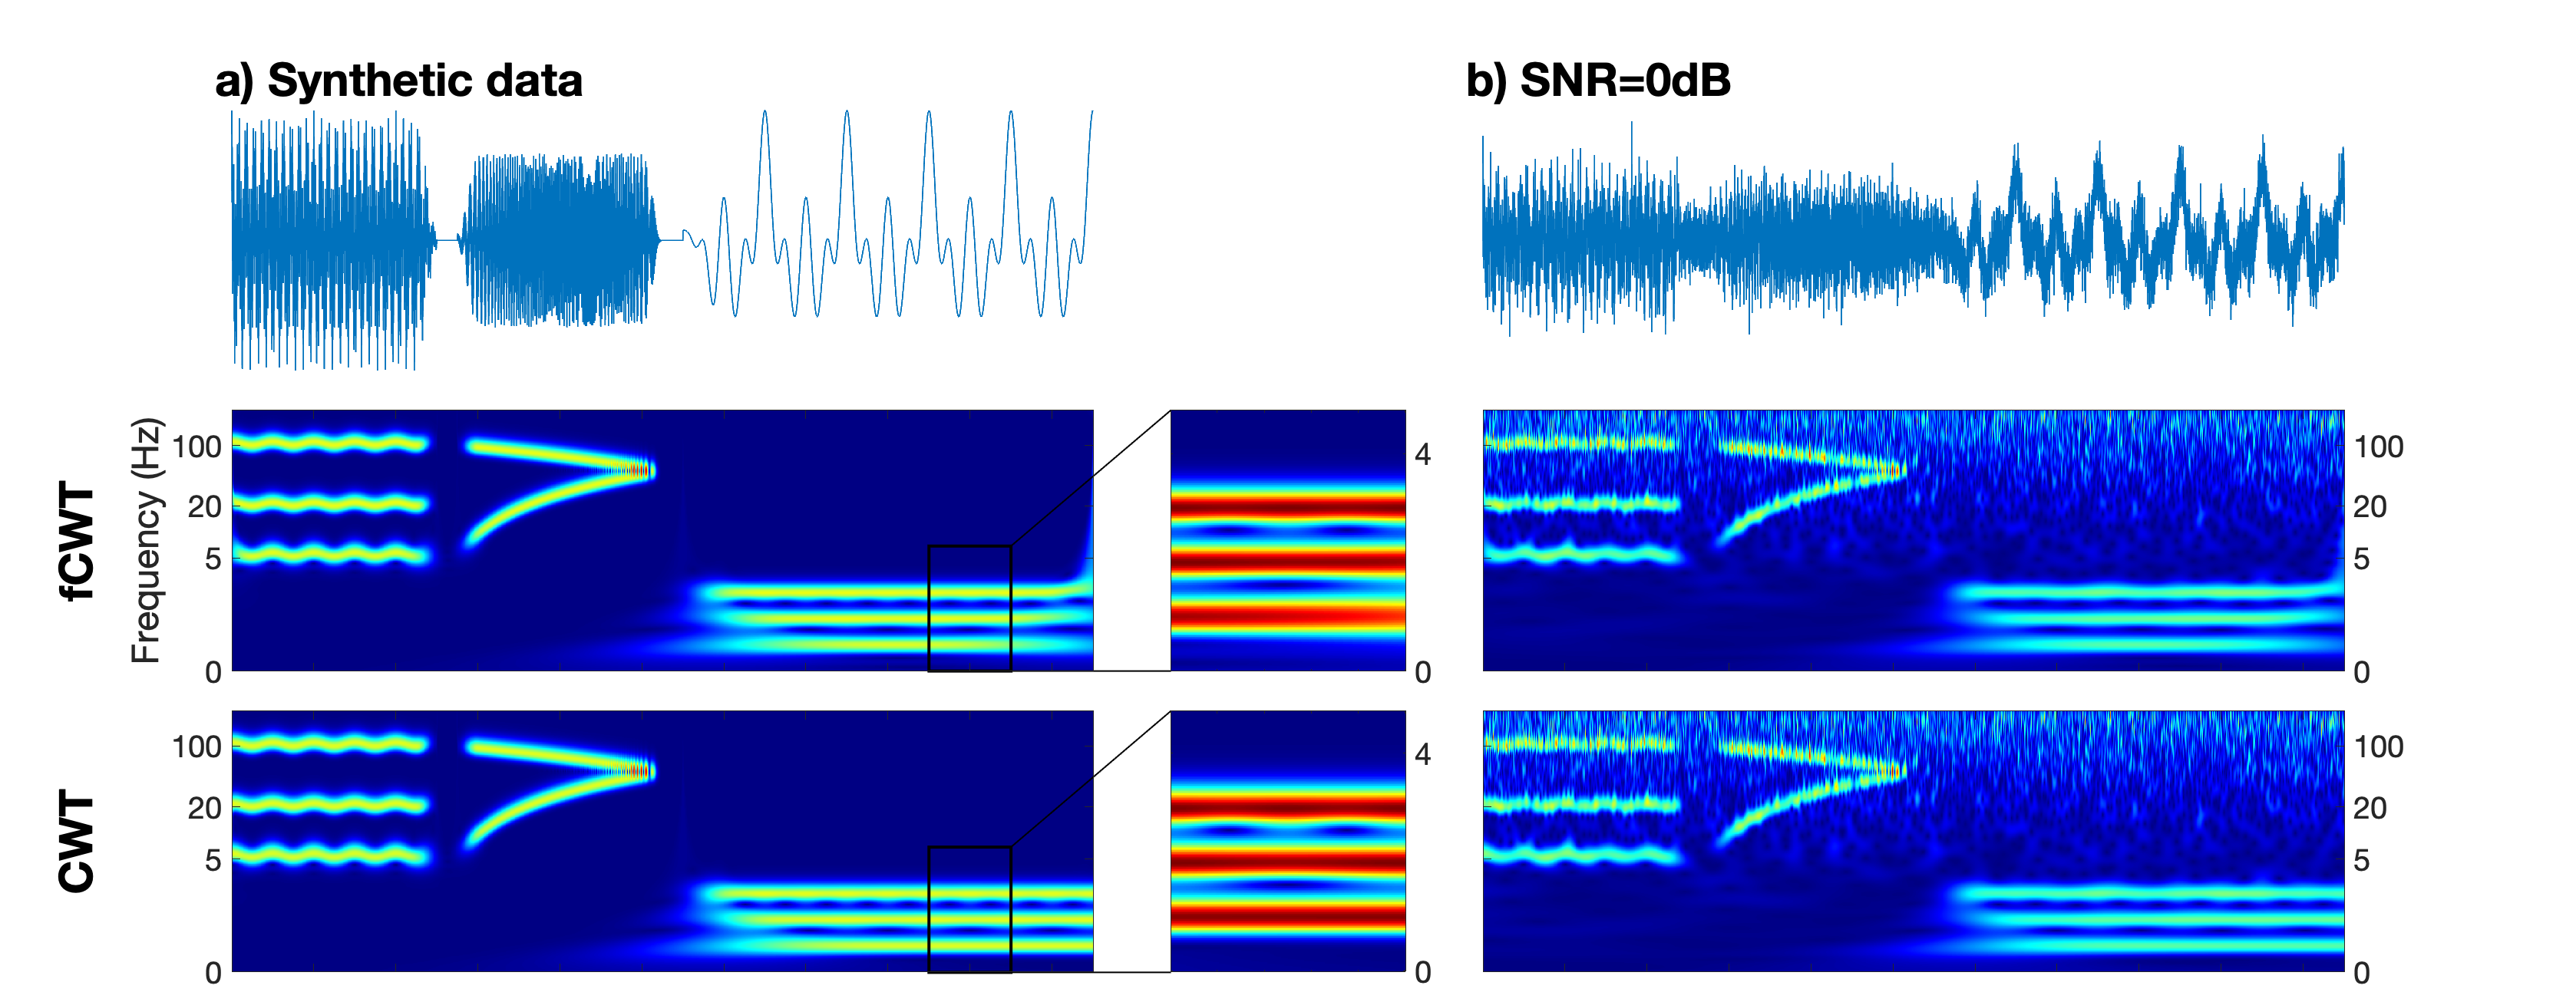

cwt_tfm_noise = abs(wt);
image(cwt_tfm_noise,"CDataMapping","scaled")

[~,ypos] = min(abs(cwtf.'-freqlabelslog.').');
yticks(ypos);
yticklabels(freqlabelslog);
xticklabels([]);
ylabel("");
ax = gca;
colormap(cm);
ax.YAxisLocation = 'right';

ax.XAxis.FontSize = 20;
ax.YAxis.FontSize = 20;